clear all;
clc;
close all;


bag_num = "9"

bag_num = "9"

bag = ros2bagreader("test13/")

bag =   ros2bagreader with properties:

           FilePath: '/home/robotics/ur3_ros2/bota_ws/test13/test13_0.db3'
          StartTime: 1.6945e+09
            EndTime: 1.6945e+09
    AvailableTopics: [1×3 table]
        MessageList: [17220×3 table]
        NumMessages: 17220


% bag_force_z = select(bag,"Topic","/force_z");
% bag_position_desired = select(bag,"Topic","/position_desired");
% bag_position_real = select(bag,"Topic","/position_real");
% bag_surface = select(bag,"Topic","/surface");
bag_data = select(bag,"Topic","/adaptive_stiffness_data");


% bag_time = select(bag,"Topic","/clock");

% mes_force_z = readMessages(bag_force_z);
% mes_position_desired = readMessages(bag_position_desired);
% mes_position_real = readMessages(bag_position_real);
% mes_surface = readMessages(bag_surface);
mes_data = readMessages(bag_data);

% mes_time = readMessages(bag_time);
n_mess = bag_data.NumMessages;


sim_time = zeros(n_mess,1);
for i = 1:n_mess
    sim_time(i) =  mes_data{i, 1}.data(1);  
end
initial_time = sim_time(1);
sim_time(:) = sim_time(:)-initial_time;
dT = sim_time(2)

dT = 0.0020



% BAG FILE DATA ORDER: 
%1  time
%2  x      x(0), // x ee
%3  y      x(1), // y ee
%4  z      x(2),  // z ee
%5  x_d      x_d(0), // x_d ee
%6  y_d      x_d(1), // y_d ee
%7  z_d      x_d(2), // z_d ee
%8  F_ext      kd(2) * position_error(2) + 2*0.707*sqrt(kd(2)) * velocity_error(2), // F_ext
%9  F_ft_x      m_ft_sensor_wrench(0), // F_ft
%10 F_ft_y     m_ft_sensor_wrench(1), // F_ft
%11 F_ft_z      m_ft_sensor_wrench(2), // F_ft
%12 F_ref_z    F_ref(2), // F_ref
%13 T      tank_energy, // Tank
%14 T_dot (energy_var_stiff + energy_var_damping) * m_deltaT, // Tank_dot
%15 kd_x      kd(0), // Kd_x
%16 kd_y      kd(1), // Kd_y
%17 kd_z      kd(2), // Kd_z
%18 kd_max      kd_max(2), // Kd_z max
%19 kd_min      kd_min(2), // Kd_z min
%20 z_surf      (z_value + 0.0025 - x(2)), // z_surf
%21 K_surf      stiffness_value, // K_surf
%22 D_surf      damping_value, // D_surf
%23 F_min      F_min(2) // F_min

time = zeros(n_mess,1);
x = zeros(n_mess,1);
y = zeros(n_mess,1);
z = zeros(n_mess,1);
x_d = zeros(n_mess,1);
y_d = zeros(n_mess,1);
z_d = zeros(n_mess,1);
F_ext = zeros(n_mess,1);
F_ft_x = zeros(n_mess,1);
F_ft_y = zeros(n_mess,1);
F_ft_z = zeros(n_mess,1);
F_ref_z = zeros(n_mess,1);
T = zeros(n_mess,1);
T_dot = zeros(n_mess,1);
kd_x = zeros(n_mess,1);
kd_y = zeros(n_mess,1);
kd_z = zeros(n_mess,1);
kd_max = zeros(n_mess,1);
kd_min = zeros(n_mess,1);
z_surf = zeros(n_mess,1);
K_surf = zeros(n_mess,1);
D_surf = zeros(n_mess,1);
F_min = zeros(n_mess,1);
F_body = zeros(n_mess,1);

for i = 1:n_mess
    time = mes_data{i, 1}.data(1);
    x(i) = mes_data{i, 1}.data(2);
    y(i) = mes_data{i, 1}.data(3);
    z(i) = mes_data{i, 1}.data(4);
    x_d(i) = mes_data{i, 1}.data(5);
    y_d(i) = mes_data{i, 1}.data(6);
    z_d(i) = mes_data{i, 1}.data(7);
    F_ext(i) = mes_data{i, 1}.data(8);
    F_ft_x(i) = mes_data{i, 1}.data(9);
    F_ft_y(i) = mes_data{i, 1}.data(10);
    F_ft_z(i) = mes_data{i, 1}.data(11);
    F_ref_z(i) = mes_data{i, 1}.data(12);
    T(i) = mes_data{i, 1}.data(13);
    T_dot(i) = mes_data{i, 1}.data(14);
    kd_x(i) = mes_data{i, 1}.data(15);
    kd_y(i) = mes_data{i, 1}.data(16);
    kd_z(i) = mes_data{i, 1}.data(17);
    kd_max(i) = mes_data{i, 1}.data(18);
    kd_min(i) = mes_data{i, 1}.data(19);
    z_surf(i) = mes_data{i, 1}.data(20);
    K_surf(i) = mes_data{i, 1}.data(21);
    D_surf(i) = mes_data{i, 1}.data(22);
    F_min(i) = mes_data{i, 1}.data(23);
    F_body(i) = mes_data{i, 1}.data(24);
end


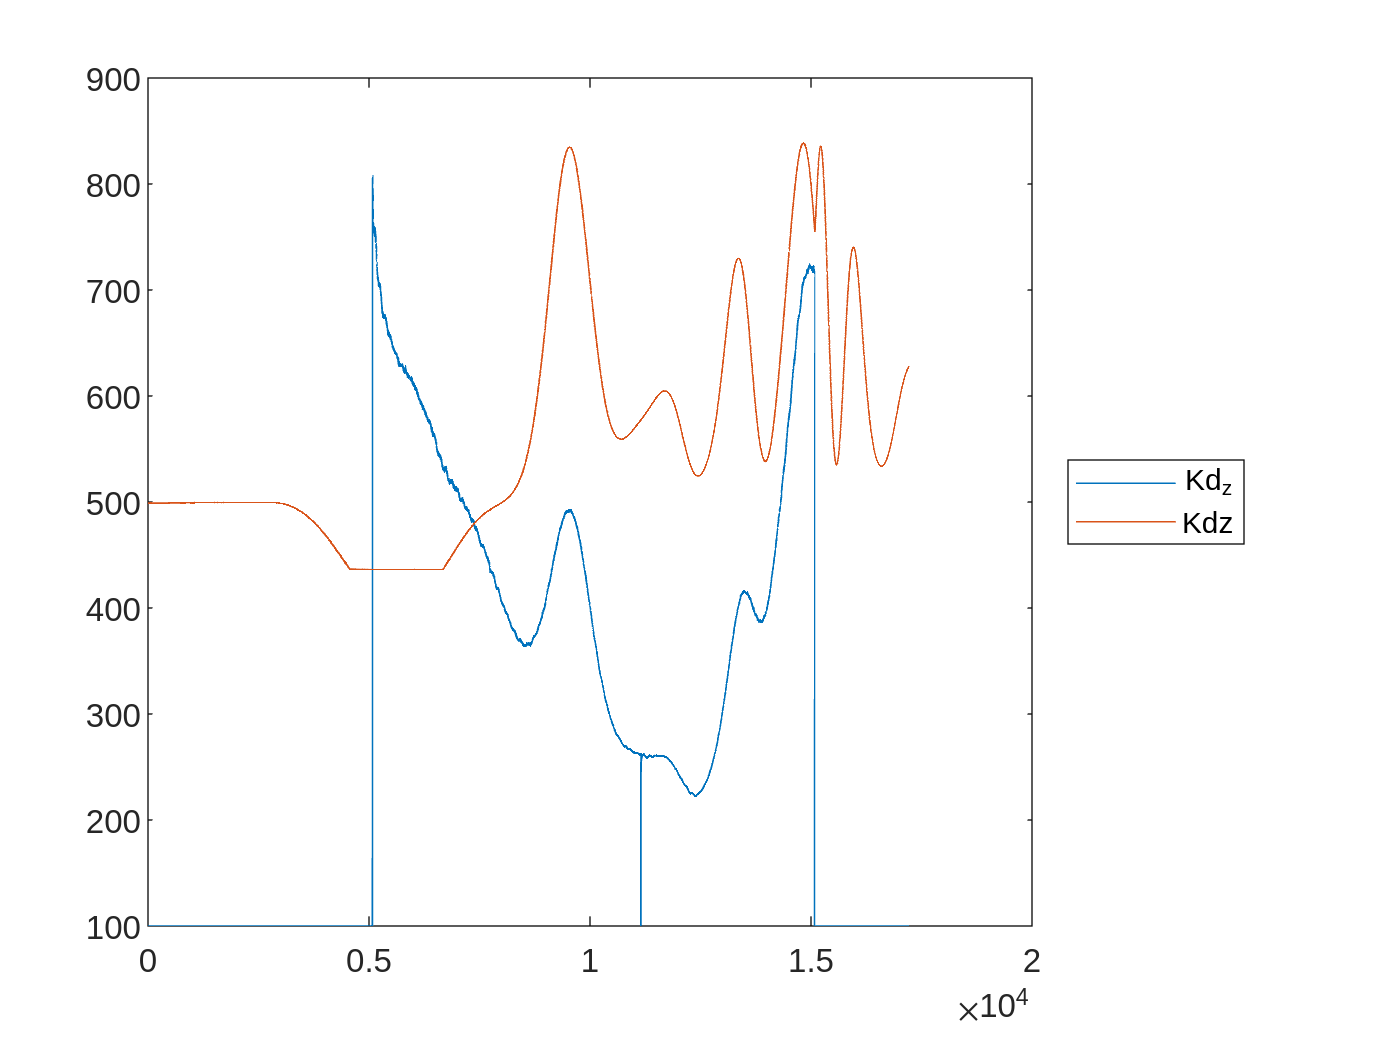



plot(kd_z)
hold on
plot(K_surf/10)
legend('Location', 'eastoutside')
legend("Kd_z","Kdz")
f = gcf;
%exportgraphics(f,strcat(bag_num,"_K.jpeg"),'Resolution',300)

hold off

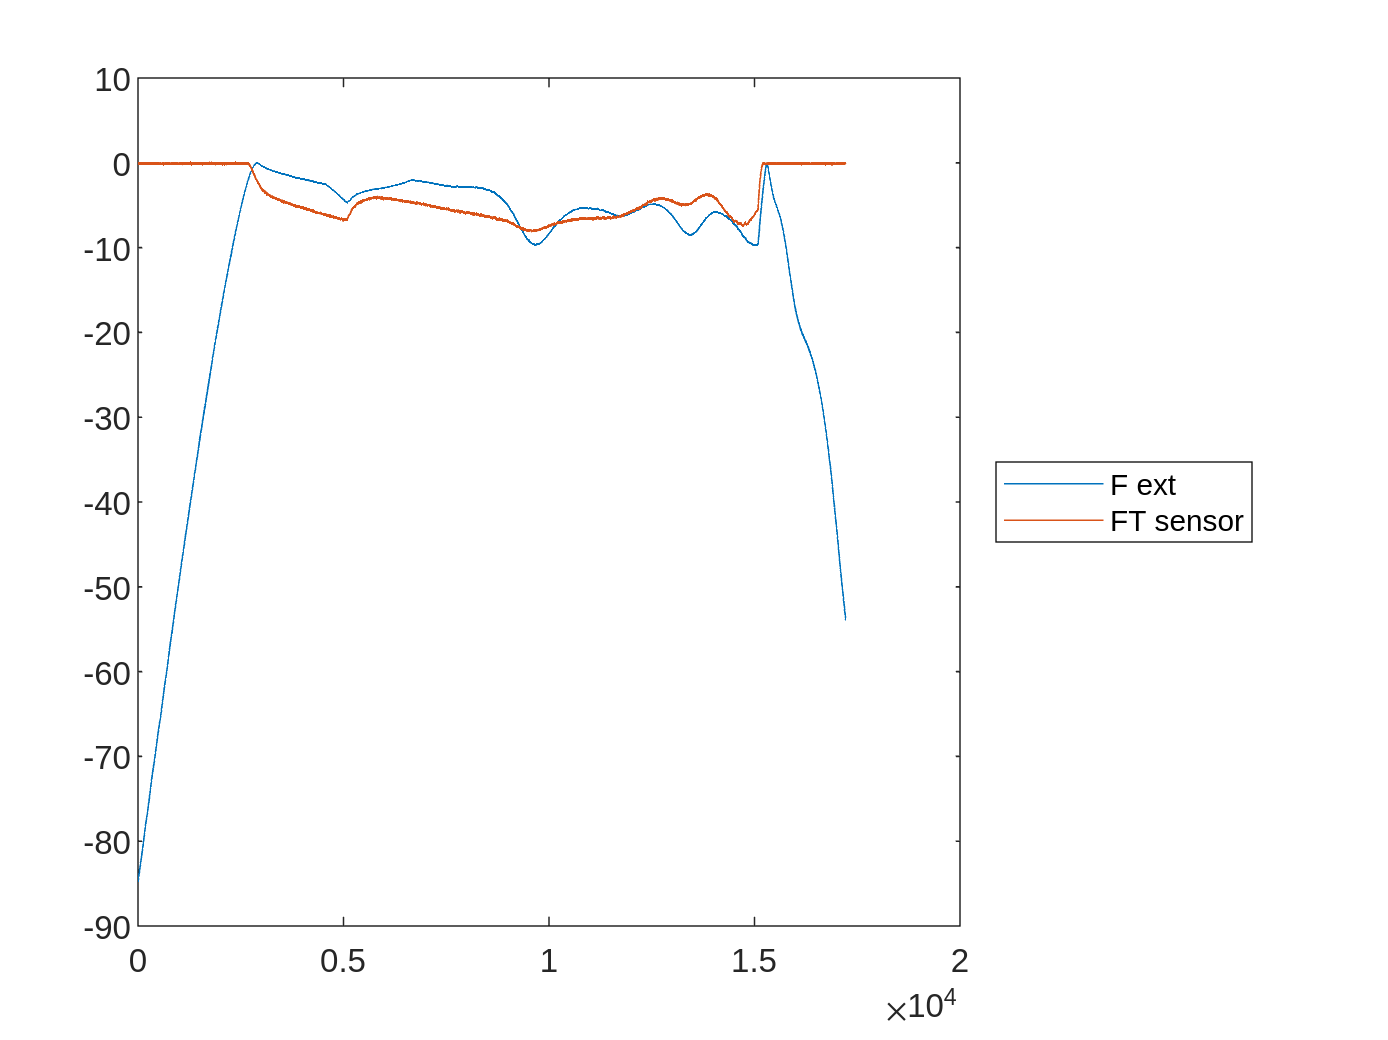




%%%%%%%%%
plot(-K_surf.*(abs(z_surf).^(1.35)))%-(K_surf .* (abs(z_d-z)).^1.35))
hold on
plot(F_ft_z)
hold on
%plot(ft_sensor)
legend('Location', 'eastoutside')
legend(["F ext","FT sensor"])
f = gcf;
%exportgraphics(f,strcat(bag_num,"_Forces.jpeg"),'Resolution',300)
hold off

%%%%%%%%%

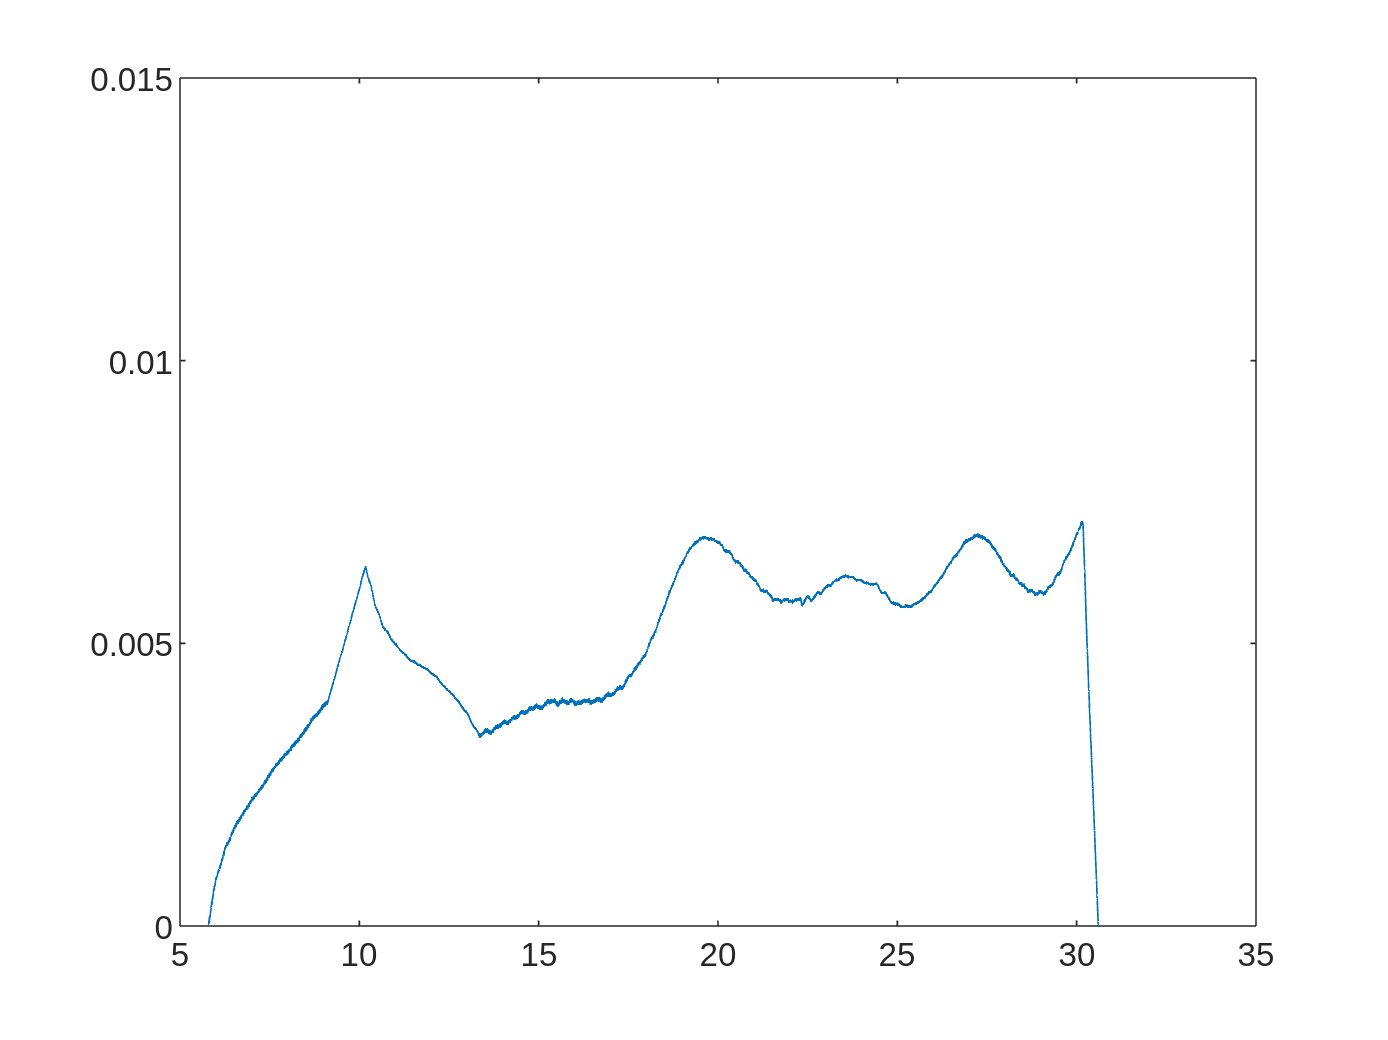



plot(sim_time,z_surf);
hold on
ylim([0,0.015])
hold off

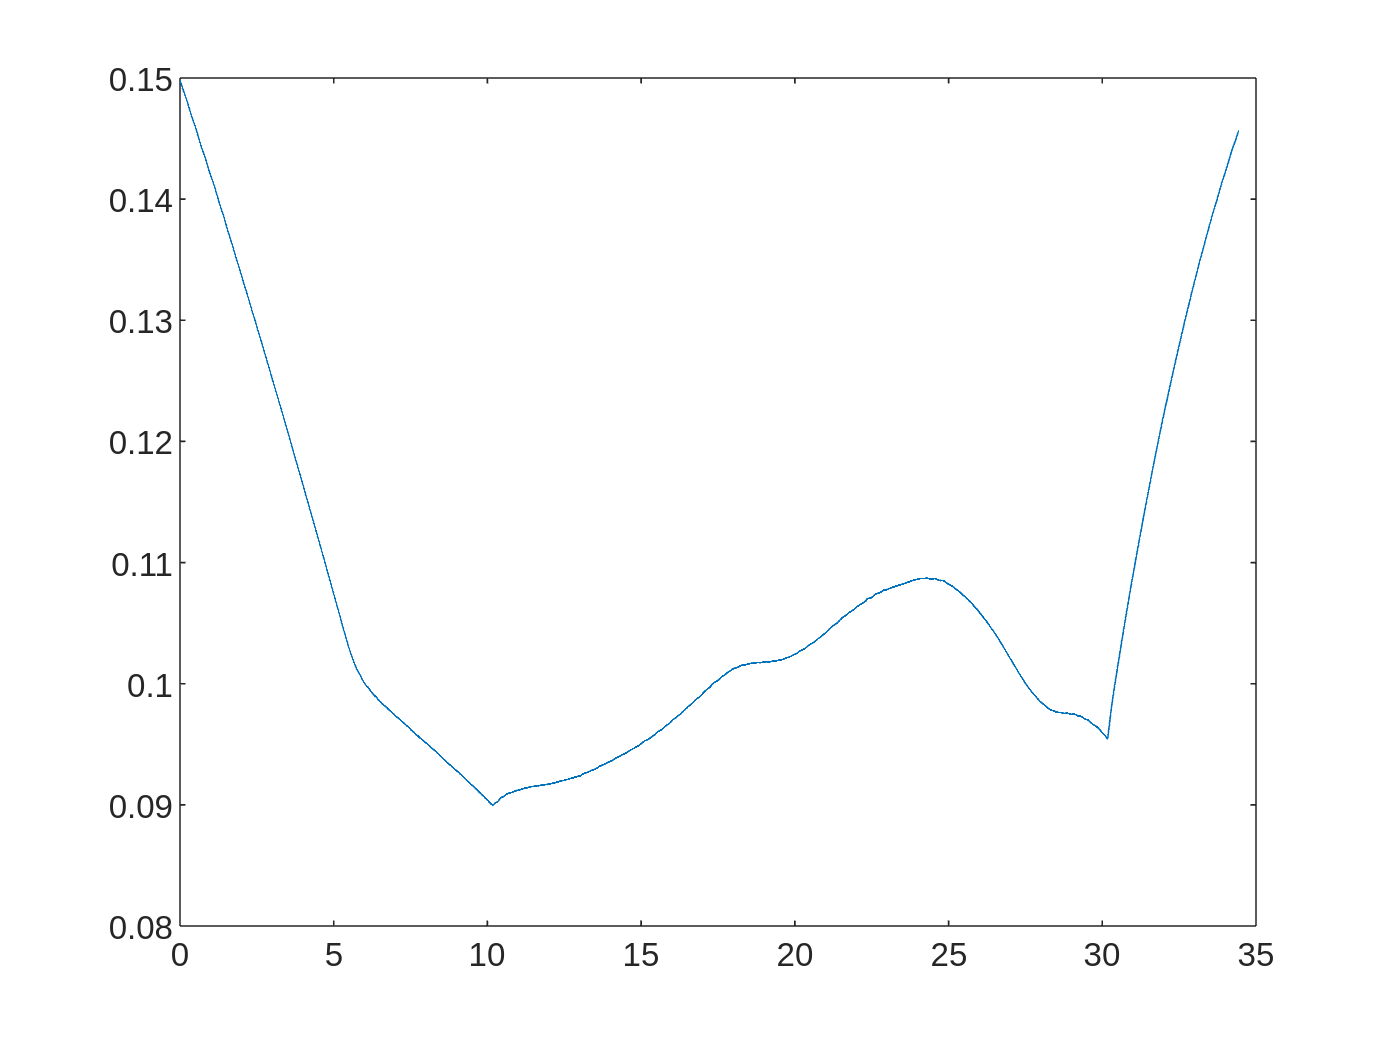

plot(sim_time, z)

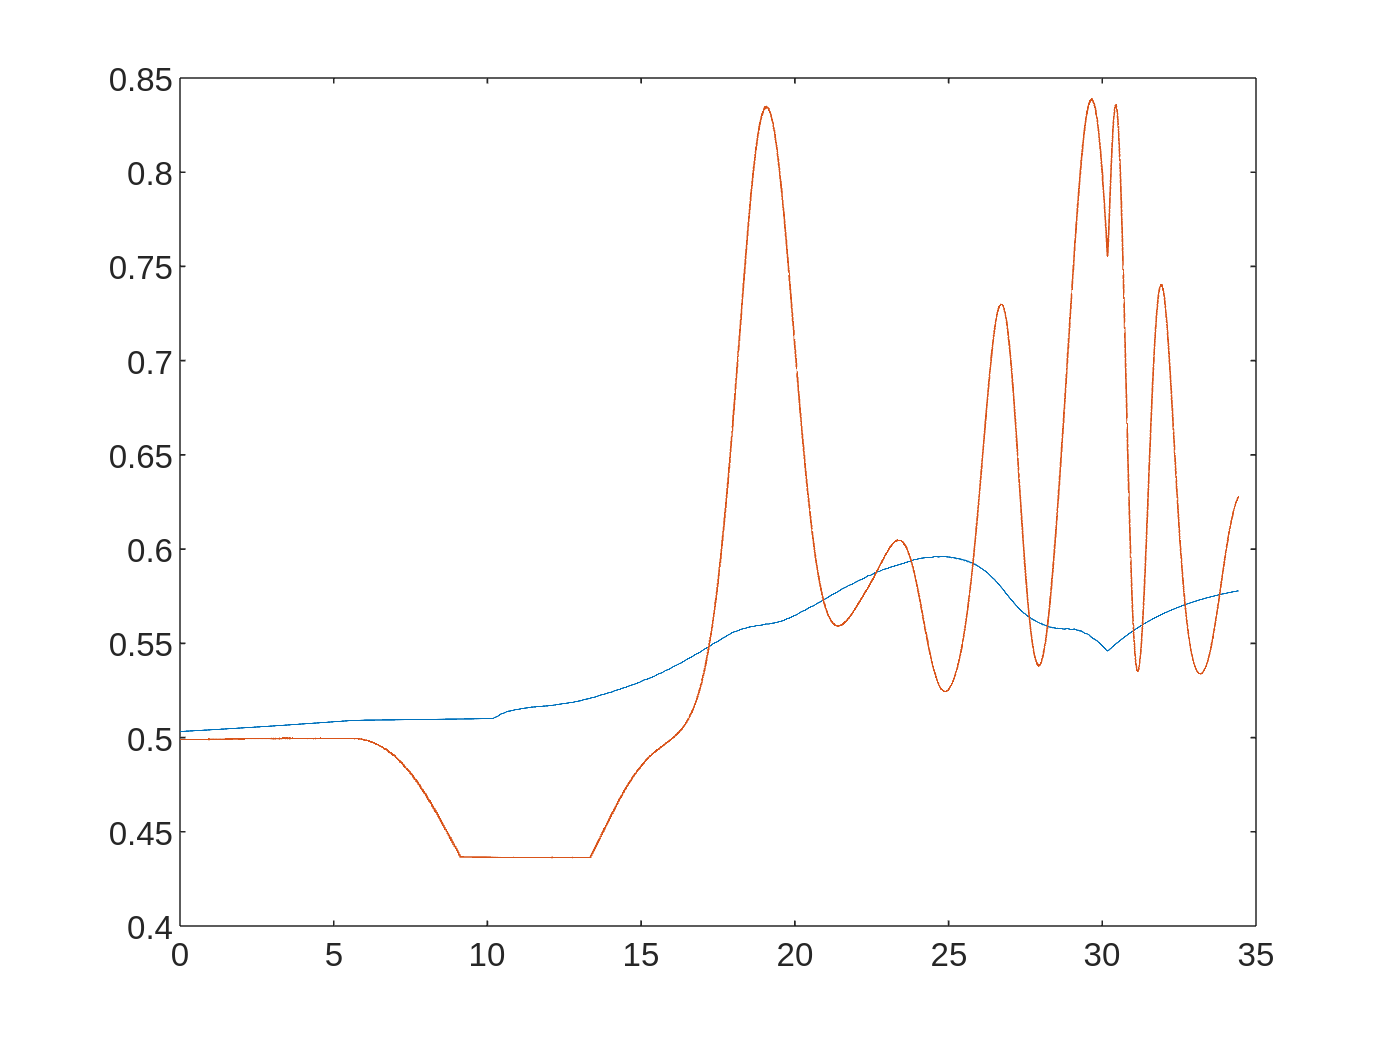

plot(sim_time,T)
hold on
plot(sim_time,K_surf/10000)
hold off

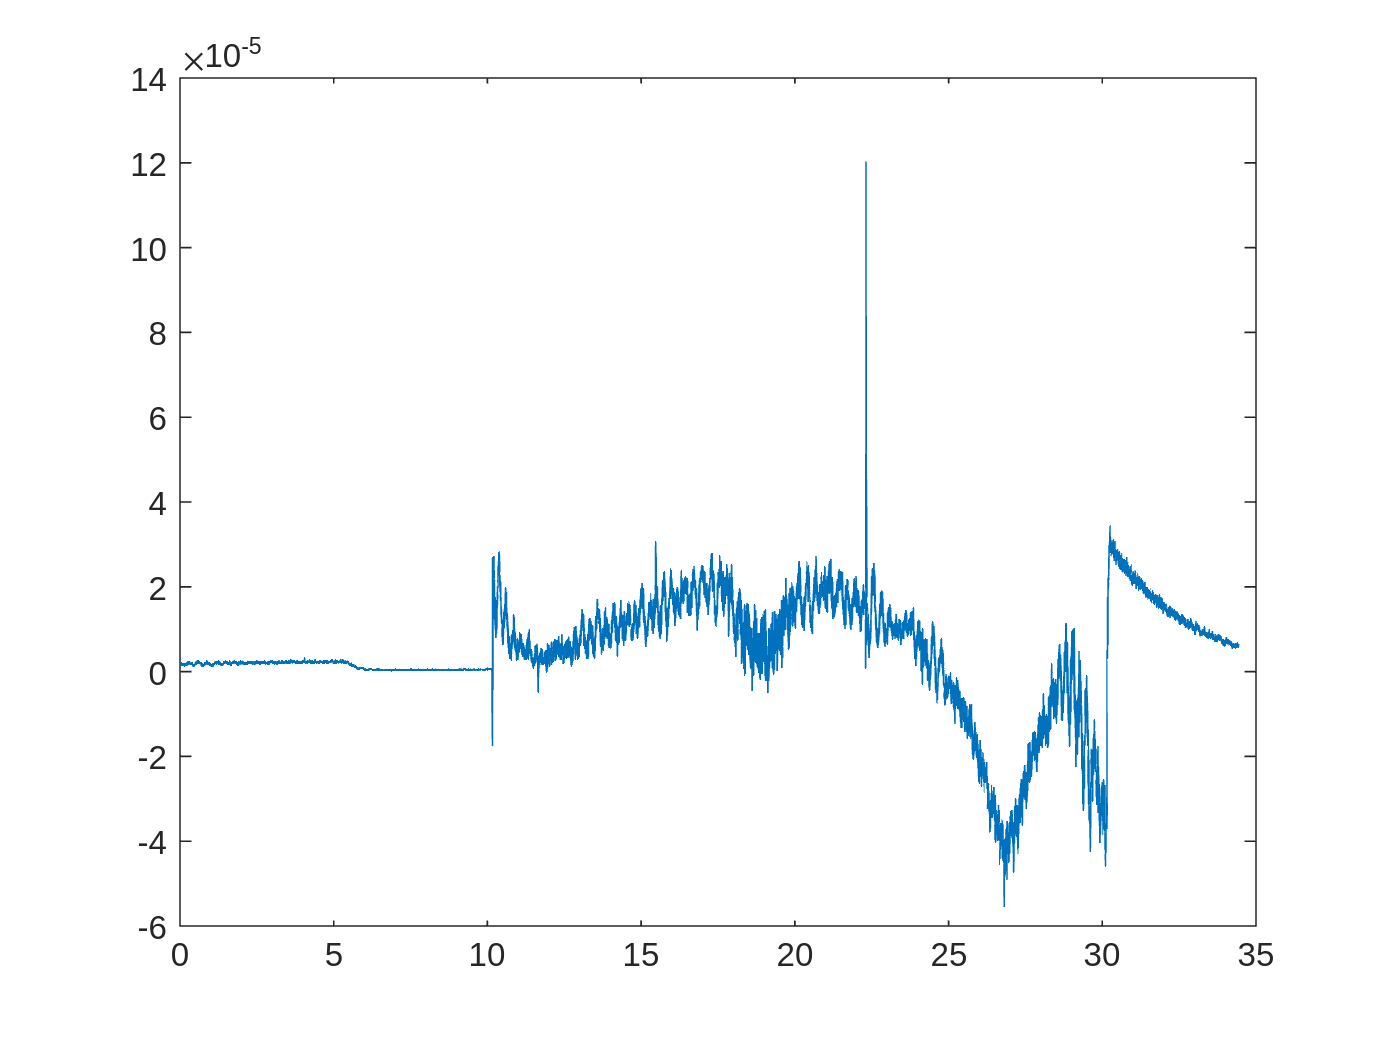


plot(sim_time,T_dot)